# Part 4: Visualize `penguins`

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

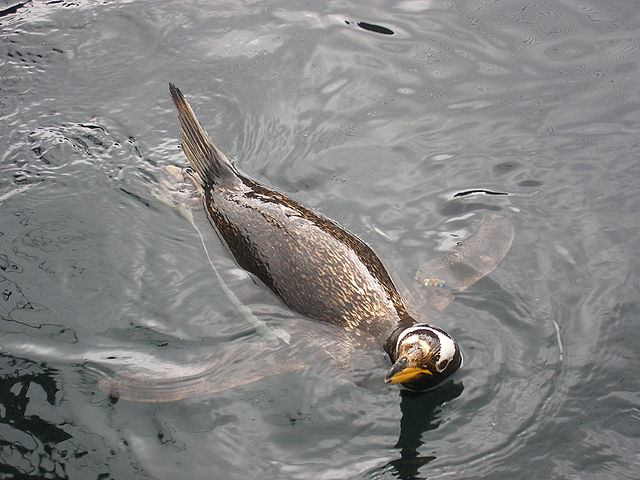

A Gentoo penguin doing the [backstroke](https://commons.wikimedia.org/wiki/File:Penguin_at_zoo.jpg). 

You've reached the most fun part! Let's see what our penguin data looks like. In this section, we'll explore how to create visual representations of this data. You should first go through the [Access Data script](matlab: edit S2_AccessData.mlx) and the [Explore Data script](matlab: edit S3_ExploreData.mlx). If you already did this but the `penguins` variable is no longer in your workspace, this block of code will add `penguins` to your workspace: 

filename = "penguins.csv";
penguins = readtable(filename);

This line of code ensures that the `penguins.species` column is correctly setup for this script:

penguins.species = categorical(penguins.species);

## 1: Plotting basics 

We know we have data from three different species of penguins. You might wonder if the data is evenly distributed among penguin species or not. For example, did the researchers collect much more data on Chinstrap penguins than on other species? 

To use plotting tools, we will need to select variables to plot. Our data is stored in a table, so let's make a variable called species that we can click on in the workspace. 

species = penguins.species;

#### Pie Chart

Now you can click on `species` in the Workspace, and then go to the Plots tab in the tool strip, and select a type of chart to make. Let's try pie. 

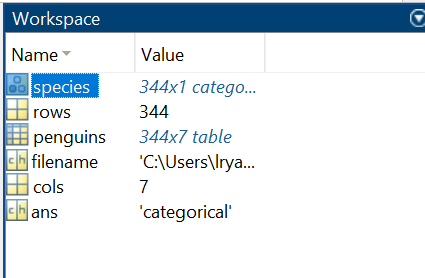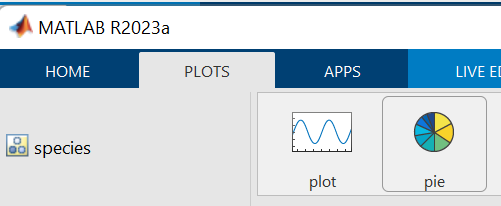

A figure will pop up showing you a pie chart of your data: 

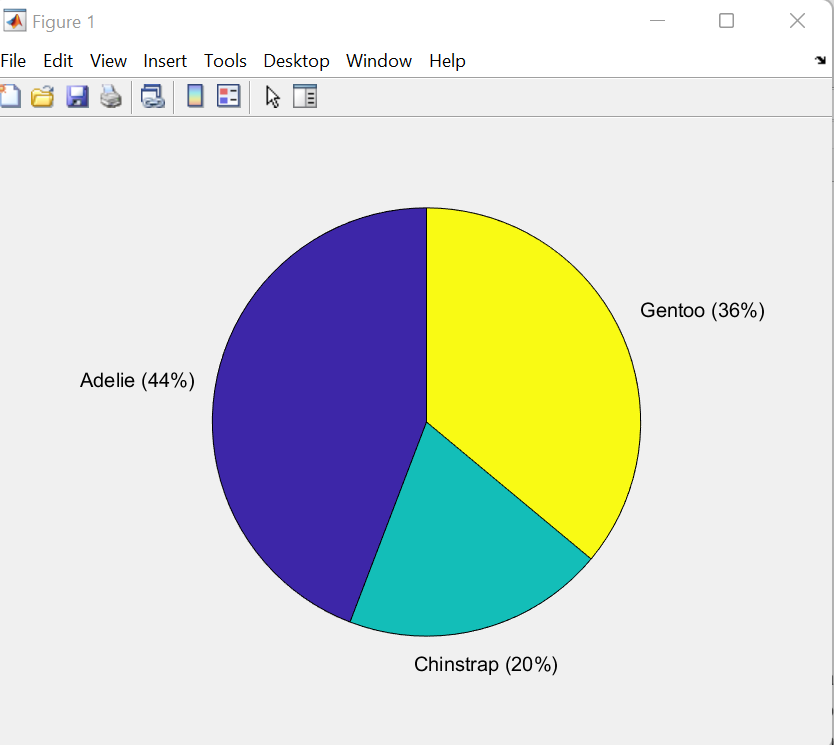

To do this manually, use the built-in function [`pie()`](https://www.mathworks.com/help/matlab/ref/pie.html):

pie(species)

While we do have the highest number of penguins from the Adelie penguin category, it seems like we have a good distribution of all three penguin species in the data.

#### Histogram

You can also try clicking the histogram plotting button or running the [`histogram()`](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html) function: 

histogram(species)

to see how many of each penguin species you have!

#### Scatter plots

  Play around with visualizing this data by selecting variables for `x` and `y` using the dropdowns below and running the cell. For example, you could try plotting bill length versus bill depth:

x = penguins.bill_length_mm;
y = penguins.bill_depth_mm; 

As you select different values of `x` and `y`, keep in mind that convention is to use the independent variable as the `x`-axis, and the dependent variable as the `y`-axis. For example, if you'd like to see how bill length affects bill depth, you'd want bill length as x and bill depth as `y`. Once `x` and `y` have been created in the workspace, use the **Create Plot** Tool below to create a scatter plot.

First, select **scatter **as the type of visualization**. **Under** Select data, **set **X** to `x` and **Y** to `y`. The scatter plot will generate automatically. 

% Create scatter of x and y
s2 = scatter(x,y,"Marker","diamond","DisplayName","y");

% Add xlabel, ylabel, title, and legend
xlabel("x")
ylabel("y")
title("y vs. x")
legend

  Alternatively, try typing 

in the code block:

 Notice how the scatter plot changes when you change x and y-- do you see any interesting trends? 

## 2: Make your plots beautiful 

#### Make plots informative by adding labels 

Right now the scatterplot we have is cool, but it's missing a lot of information! We need to make sure we always label the `x` and `y` axes and give the plot a title so that whoever is looking at the graph knows exactly what they are looking at. 

It's pretty easy to add this kind of information [using MATLAB® commands](https://www.mathworks.com/help/matlab/titles-and-labels.html?s_tid=CRUX_lftnav).

Run: 

xlabel("Bill Length (mm)")
ylabel("Bill Depth (mm)")
title("Bill length vs. depth")

  Try plotting different values for `x` and `y` than bill length and depth and change your `xlabel`, `ylabel`, and `title`, respectively, in the code block above! 

#### Make plots more aesthetically pleasing

Now our plot is correctly labeled and it is interpretable. This is important when we're showing other people our data. When MATLAB is making these plots, it just ignores and doesn't plot any NaNs. 

Let's look at making the plot more aesthetically pleasing. You can add inputs to the scatter function- here we specify a marker size (50) and color, green ("g"): 

s = scatter(x, y, 50, "g"); 
xlabel("Bill Length (mm)")
ylabel("Bill Depth (mm)")
title("Bill length vs. depth")

  There are several color options built in that can use for basic plotting. Change the `"g"` in the code block above to a different letter. Try r, m, b, c, y, or k.

You can also type:

in the **Command Window** to see what other options are available to use when creating a scatter plot. 

***Pro tip:*** In this case, the [scatter plot itself](https://www.mathworks.com/help/matlab/ref/scatter.html#d124e1400887) is saved as an object called `s`. This allows us to change aesthetic things about the plot without creating a new plot. If you type `s.` in the **Command Window** and then press **Tab **on your keyboard, you'll see all the options you have for making adjustments to the plot. Such [tab completion](https://www.mathworks.com/company/newsletters/articles/avoiding-repetitive-typing-with-tab-completion.html) can be very helpful to learn more about function options. 

Examples: 

s.Marker = "^"; %change marker itself
s.MarkerFaceColor ="flat"; %fill the markers 

## 3: More advanced plotting

Let's again plot **bill length versus bill depth**. 

Instead of using `x` and `y` as our variables, let's pull our data directly from `penguins` and plot it. 

  Try typing `penguins.` in the code box below. You'll see the variables of `penguins`. For example, `penguins.bill_length_mm` will return the array of bill lengths for each penguin. 

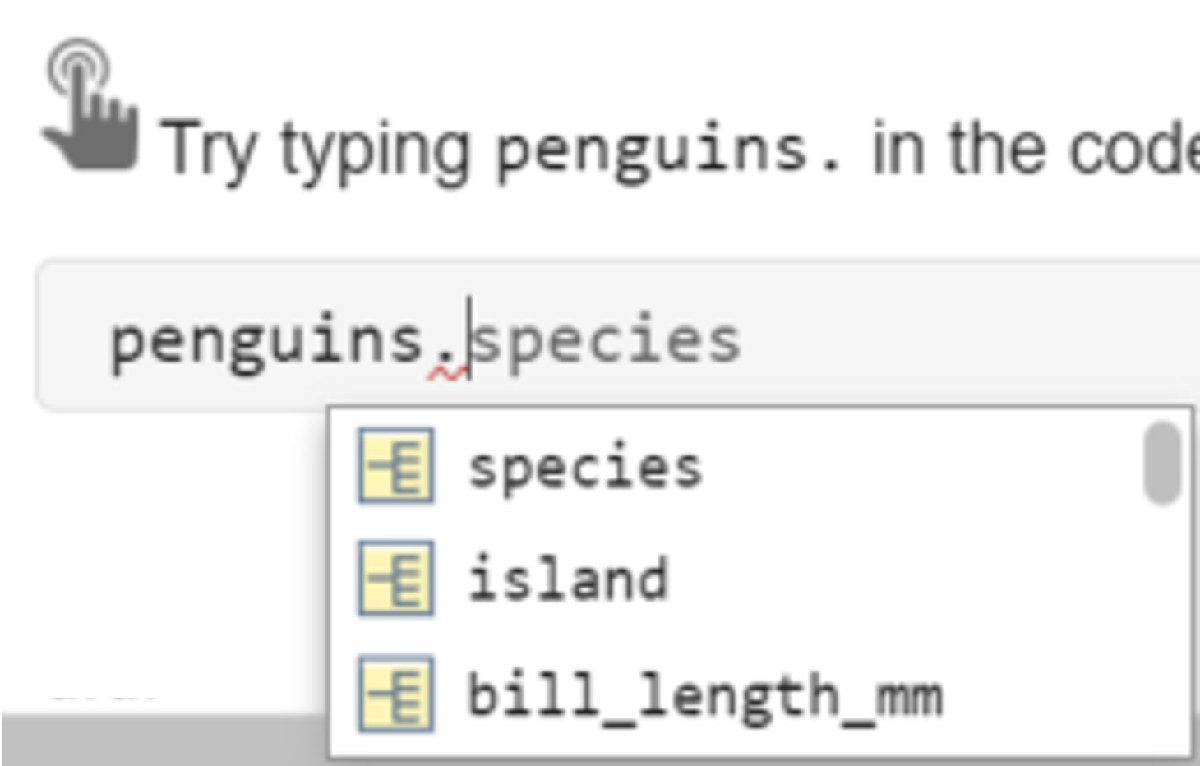

This kind of interactive coding option is really useful because it makes it much faster to type the variables you'd like to plot and much easier to avoid spelling mistakes that would mess up your code. 

  Plot bill length versus bill depth directly from `penguins`. Type: 

into the code block and run the section: 

It is better to create a scatter plot like this rather than using `x` and `y` as the variables because if someone else reads your code, it is immediately clear to them what you are plotting.

xlabel("Bill Length (mm)")
ylabel("Bill Depth (mm)")
title("Bill length vs. depth")

Looking at this plot, it looks to me like there could be 3 distinct groups in this plot. Is it possible that bill size is clustered by species? 

#### Scatter plot by species

Run:

gscatter(penguins.bill_length_mm, penguins.bill_depth_mm, species)
xlabel("Bill length (mm)")
ylabel("Bill depth (mm)")
title("Bill Length versus Depth, by species")

[`gscatter()`](https://www.mathworks.com/help/stats/gscatter.html#d124e506251) is another built-in MATLAB function,  where `gscatter(x,y,g) `scatters `x` and `y` as normal and then colors by species group (the third input to the function, `g`). Note that `gscatter()` automatically adds a legend to our plot which tells us which species corresponds to which color. 

There is a pretty clear distribution of bill sizes by species! 

#### Scatter plot by island

You can try sorting by other things as well. Let's try sorting by island. 

island = categorical(penguins.island); 

symb = ['*','o', '^'];
gscatter(penguins.bill_length_mm, penguins.bill_depth_mm,island,'',symb)
xlabel("Bill length (mm)")
ylabel("Bill depth (mm)")
title("Bill Length versus Depth, by island")

We also changed the symbols used to visualize each island in this graph. You can give `gscatter()` a set of symbols to plot as the 4th input. Differentiating islands not just by color but also by symbol can help as a visual aid to whoever you are presenting the data to. 

This graph makes it look like bill size is more dependent on species classification than on island location. Comparing the two `gscatter()` plots, it looks like for the most part, Gentoo penguins are on Biscoe Island, Chinstrap penguins are on Dream island, and Adelie penguins are split among all three islands. Is this true? Let's test: 

#### Swarm chart

swarmchart(species,island)
title("Which species live on each island?")
xlabel("Species")
ylabel("Island")

One way to look at this data is a [swarm chart](https://www.mathworks.com/help/matlab/ref/swarmchart.html), which plots a dot for each penguin in each category. Indeed, this chart shows that Chinstrap penguins are all on Dream Island, Gentoo penguins are all on Biscoe, and Adelie penguins are relatively evenly split between the three islands. Interesting! 

There are a lot of different ways you can visualize data. Check out the [MATLAB Plot Gallery](https://www.mathworks.com/products/matlab/plot-gallery.html) to learn more. 

## 4: Try it out

####  Exercise 1: Plot flipper length versus body mass.

Exercise answers are provided at the bottom of this module.

We are plotting flipper length versus body mass.  The x value to plot has been filled out here, fill in the y value: 

scatter(penguins.flipper_length_mm, y)
title("Flipper length versus body mass")
xlabel("Flipper Length (mm)")
ylabel("Body mass (g)")

Next, try modifying this plot so it's color-coded by species. 

Fill out the value for y (body mass) and the value for group (group by species here): 

gscatter(penguins.flipper_length_mm, y, group)
title("Flipper length versus body mass, grouped by species")
xlabel("Flipper Length (mm)")
ylabel("Body mass (g)")

####  Learn to plot a single species

If we want to only look at the species 'Gentoo', we can [find which rows of the penguin's table correspond to that species](https://www.mathworks.com/matlabcentral/answers/137316-select-rows-given-a-condition). We can compare the `penguins.species` column of our table to the [string](https://www.mathworks.com/help/matlab/ref/string.html) 'Gentoo' by using a double equal sign (==). The following line of code goes through each row of `penguins.species` and determines if the value of that row equals 'Gentoo'. Then `rows_gentoo` will contain a 1 in every row where` penguin.species` equals 'Gentoo', and all other rows will contain a 0.  

rows_gentoo = (penguins.species == "Gentoo") 

Going back to indexing, we can make a new table of only Gentoo penguins by doing: 

gentoos = penguins(rows_gentoo,:) %this makes a table by selecting the rows of penguin that have 'Gentoo' as a species value, and using all the columns in that row

The colon (`:`) in indexing means 'all', so all columns will be included. Only rows where `rows_gentoo` contained a 1 will be included. 

For a review of indexing, return to the [MATLAB Onramp](https://matlabacademy.mathworks.com/R2023a/portal.html?course=gettingstarted#chapter=5&lesson=2) section on indexing. 

Now we have a new variable called `gentoos`, which has 124 rows (the number of Gentoo penguins in the dataset), and 7 columns, which is the same number of columns or variables as in `penguins`. 

Let's plot flipper length versus body mass for Gentoo penguins only. 

scatter(gentoos.flipper_length_mm, gentoos.body_mass_g)
title("Flipper length versus body mass, Gentoo")
xlabel("Flipper Length (mm)")
ylabel("Body Mass (g)")

Now, can we color the plot based on sex? 

sex_gent = categorical(gentoos.sex);
gscatter(gentoos.flipper_length_mm, gentoos.body_mass_g, sex_gent)
xlabel("Flipper Length(mm)") 
ylabel("Body Mass(g)") 
title("Flipper Length versus Body Mass, Gentoos, sorted by sex") 

It appears that flipper length and body mass scale with each other, and as is expected, males have both larger flipper length and body mass than females. 

####  Exercise 2: Plot flipper length versus body mass for a single species

For each task here, you only need to write one line of code! 

A: Find the rows of penguins that correspond to only one species (choose your favorite). 

B: Create a new table of only that species of penguin. 

C: Make a scatter plot of flipper length versus body mass for that species. 

D: Add an x-label. 

E: Add a y-label. 

F: Add a title. 

G: Color the plot based on sex using `gscatter()`. 

####  Exercise answers

***Exercise 1: ***

scatter(penguins.flipper_length_mm, penguins.body_mass_g);

gscatter(penguins.flipper_length_mm, penguins.body_mass_g,  penguins.species);

***Exercise 2: ***

rows_chin = penguins.species == "Chinstrap"; % A
chinstrap = penguins(rows_chin,:); % B
scatter(chinstrap.flipper_length_mm, chinstrap.body_mass_g); % C 
xlabel("Flipper Length(mm)") % D 
ylabel("Body Mass(g)") % E
title("Flipper Length versus Body Mass, Chinstrap") % F 
gscatter(chinstrap.flipper_length_mm, chinstrap.body_mass_g, categorical(chinstrap.sex)) % G

% Bonus points for adding an x and y label and title to your grouped
% scatter! 
xlabel("Flipper Length(mm)")  
ylabel("Body Mass(g)") 
title("Flipper Length versus Body Mass, Chinstrap, sorted by sex") 

  Change a few lines of the code to examine the third species you haven't looked at yet! 

In sum, we've learned how to import a table and use a variety of tools in MATLAB to examine and visualize the data in that table. The next module will explore how to apply statistical methods to further analyze and understand this data. Continue to the problem set to try more of these data visualization methods for yourself. 

[*Go to next script (Problem Set)*](matlab: edit S5_ProblemSet.mlx)

[*Return to introduction*](matlab: edit S1_Introduction.mlx)